# **Guide to MATLAB Assignment 6:   FACE IT (Graphing Linear Transformations in Two Dimensions)**

**Overview.   **In this assignment, MATLAB graphics capabilities are used to visualize linear transformations of the plane.    

**Academic integrity note.   **Each student must submit their own work.   Submission of the work of others as your own is a serious violation of the University Academic Integrity Policy.

**Making a face.** A collection of points $\{\bf f_1,\bf f_2,\dots,\bf f_N\}$in two dimensions is defined below to draw a face.    The points will be stored in a 2xN array called `face. `This array will be assembled by catenating arrays representing a sampling of points from the different parts of the face:   

- the outline (`outline`) which is a unit circle centered at the origin, 

- the left eye (`leye) `which is a circle of radius 0.1 centered at (0.4,0.4),

- the right eye` (reye) `which is a horizontal line segment from (-0.5,0.3) to (-0.5,0.3),

- the smile (`smile`) which is an arc of radius 0.5 with the origin as the center of curvature and angle (with respect to the horizonal) from $\frac{5\pi }{4\;}$ to $\frac{7\pi }{4\;}$.

%%%%%% Make a face
theta=0.0:0.01:2*pi; 
outline = [ cos(theta); sin(theta)];                     % outline of face 
leye    = [0.4+0.1*cos(theta);0.4+0.1*sin(theta)];       % left eye
reye    = [-0.5:0.01:-0.3; 0.4*(1+0*(-0.5:0.01:-0.3))];  % right eye
theta   = 5*pi/4:0.01:7*pi/4;
smile   = [0.5*cos(theta); 0.5*sin(theta)];              % smile
face    = [outline leye reye smile];                     % face assembled

**Drawing a face.**    The MATLAB `plot `command is used to create images on the computer screen.   Here we use the plot command to mark, with a dot, each of the points in `face`.    The `axis equal `command ensures that the vertical and horizontal distances on the screen have the same scale.

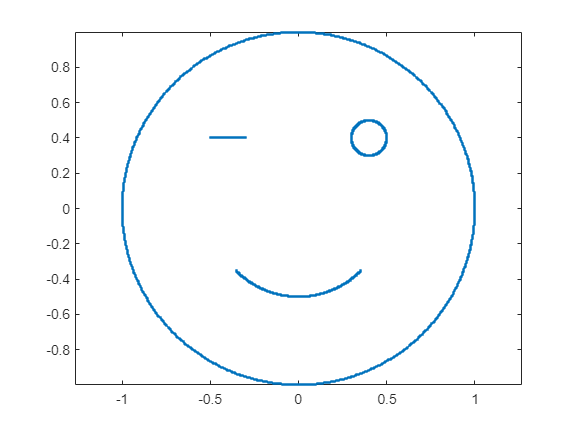

%%%%%% Plot a face
plot(face(1,:),face(2,:),'.')        % places a dot at each point (face(1,k),(face(2,k)) k=1,...
axis equal

**Facial transformation.   ** A 2x2 matrix defines a linear transformation of the plane to itself.    Here we choose a matrix that rotates the plane clockwise through an angle of $\frac{\pi }{3}$:

                                            $A=\left\lbrack \begin{array}{cc}
\cos \left(\frac{\pi }{3}\right) & \sin \left(\frac{\pi }{3}\right)\\
-\sin \left(\frac{\pi }{3}\right) & \cos \left(\frac{\pi }{3}\right)
\end{array}\right\rbrack$.

Multiplying each column of `face on the left `by *A *rotates the column about the origin.    (Note:  $A[{\bf f}_1~ {\bf f}_2~\cdots~{\bf f}_N] = [A{\bf f}_1~A{\bf f}_2~\cdots~A{\bf f}_N]$.)

%%%%%% Standard matrix for a clockwise rotation by pi/3
theta = pi/3;
A = [cos(theta) sin(theta); -sin(theta) cos(theta)]

A =     0.5000    0.8660
   -0.8660    0.5000


Tface = A*face;     % rotates each point in face storing the result in Tface

**Visualizing a face transformed.   **To visualize the transformation, we plot the original image, the points in `face, `and the transformed image, the points in `Tface, `side by side.    To do this, we use the MATLAB `subplot(m,n,p)` command which creates an `mxp` array of windows and selects the `p`th one in which to draw. 

%%%%%% Plotting    
subplot(1,2,1)            % define 1 row of two windows and select first
plot(face(1,:),face(2,:),'.')
axis equal
axis([-2 2 -2 2])
title('Domain')
subplot(1,2,2)            % select th second of the two window defined above
plot(Tface(1,:),Tface(2,:),'.')
axis equal
axis([-2 2 -2 2])
title('Codomain')


**Saving face.**   The image produced in this way can be printed or saved to files in various formats using the `print `command.    In particular, the command `print('myfaces','-djpeg') `will save the image in jpeg format in a file named `myfaces.jpeg`

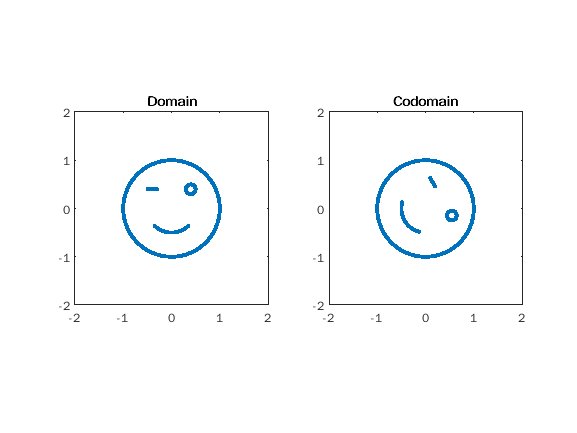

print('myfaces','-djpeg');

**Assignment.     **For each of the four matrices defined below plot the face and its transformation by the matrix.    Save each plot in a different jpeg file.   In a Microsoft Word document give the standard matrix for each transformation followed immediately by the plot.   (The jpeg file should be imported into the Word document.)  An example of the proper format of the solution is found in Canvas (Format Example for MATLAB Assignment 6.doc).   Upload the Word document to Canvas.

A1 = [-2 0; 0 1];                             
A2 = 0.5*[cos(pi) -sin(pi); sin(pi) cos(pi)];     
A3 = 0.2*[3 2; 2 3];                     

The fourth matrix is randomly generated and should be unique to you.    To be sure that it is unique, you should assure that the command `rng('shuffle') `is correctly executed just prior to using `randn` to generate your matrix.    It is also important that you accurately report your unique matrix in your submission (be sure to record the components of this matrix to at least three decimal places).

rng('shuffle')         % This command must be correctly executed immediately before defining A4
A4 = randn(2);         % This must immediately follow the rng('shuffle') command